# Notebook 3: KCC Exploration

This notebook is meant to be an exploration into the different kernels selected for my thesis, and comparing the correlations against eachother. This is going to be a backdrop for the detection simulation that will be conducted later in the research. The main goal is going to just be the comparisons in the kernels. 

Constants:

            All training will be the same $\rightarrow$Impulse trainer

            All correlations will be conducted on the same data set and on the same reference signal 

The kernels used:

            RBF: 

                
$$K(x,y) = exp(\frac{-(x^2 + y^2)}{2\sigma})$$


            Cubic:

                
$$K(x,y) = -(x \odot y + 1)^3$$


            Linear-Abs:

                
$$K(x,y) = |(x + y)|$$


## Initial Setup

% --Setup
    clear; clc; format compact; close all; 
    % cd("/home/samkramer/Desktop/Engineering/Chirp Detection Algorithm/MAT Notebooks")

% --Declare Basic Signal

    % --Signal Parameters
        T = 1;              % Signal Period T (s)
        fs = 10000;         % Sample Rate (Hz)
        t = 0:1/fs:T;
        f = 10*2*pi;        % Frequency (Hz)

    % --Create signal
        amplitude = 0.25;
        envelope = amplitude.* sin(pi*t);
        ref_signal = envelope .* sin(f*t);

% --Creating sample signal
    t1 = 0:1/fs:5;
    amplitude = 1;
    envelope = amplitude.* sin(pi*t1);
    signal = envelope .* sin(f*t1);
    noisy_signal = randi(100,1,length(t1))./400 + signal;
    signal = noisy_signal - mean(noisy_signal);

% --Zero pad signals to make same length
    diff = length(signal) - length(ref_signal);
    pad = zeros([1, diff]);
    ref_signal_long = [ref_signal, pad];

% --Declare Trainer
    z = linspace(0,5.5, length(t1)./2);
    g_bessel_1 = besselj(0,z);
    z = linspace(0,5.5, (length(t1)./2) + 1);
    g_bessel_2 = besselj(0,z);
    g_x = [flip(g_bessel_2), g_bessel_1];
    g_hat = fft(g_x);

% --Declare xf and yf
    xf = fft(signal);
    yf = fft(ref_signal_long);

## Correlations

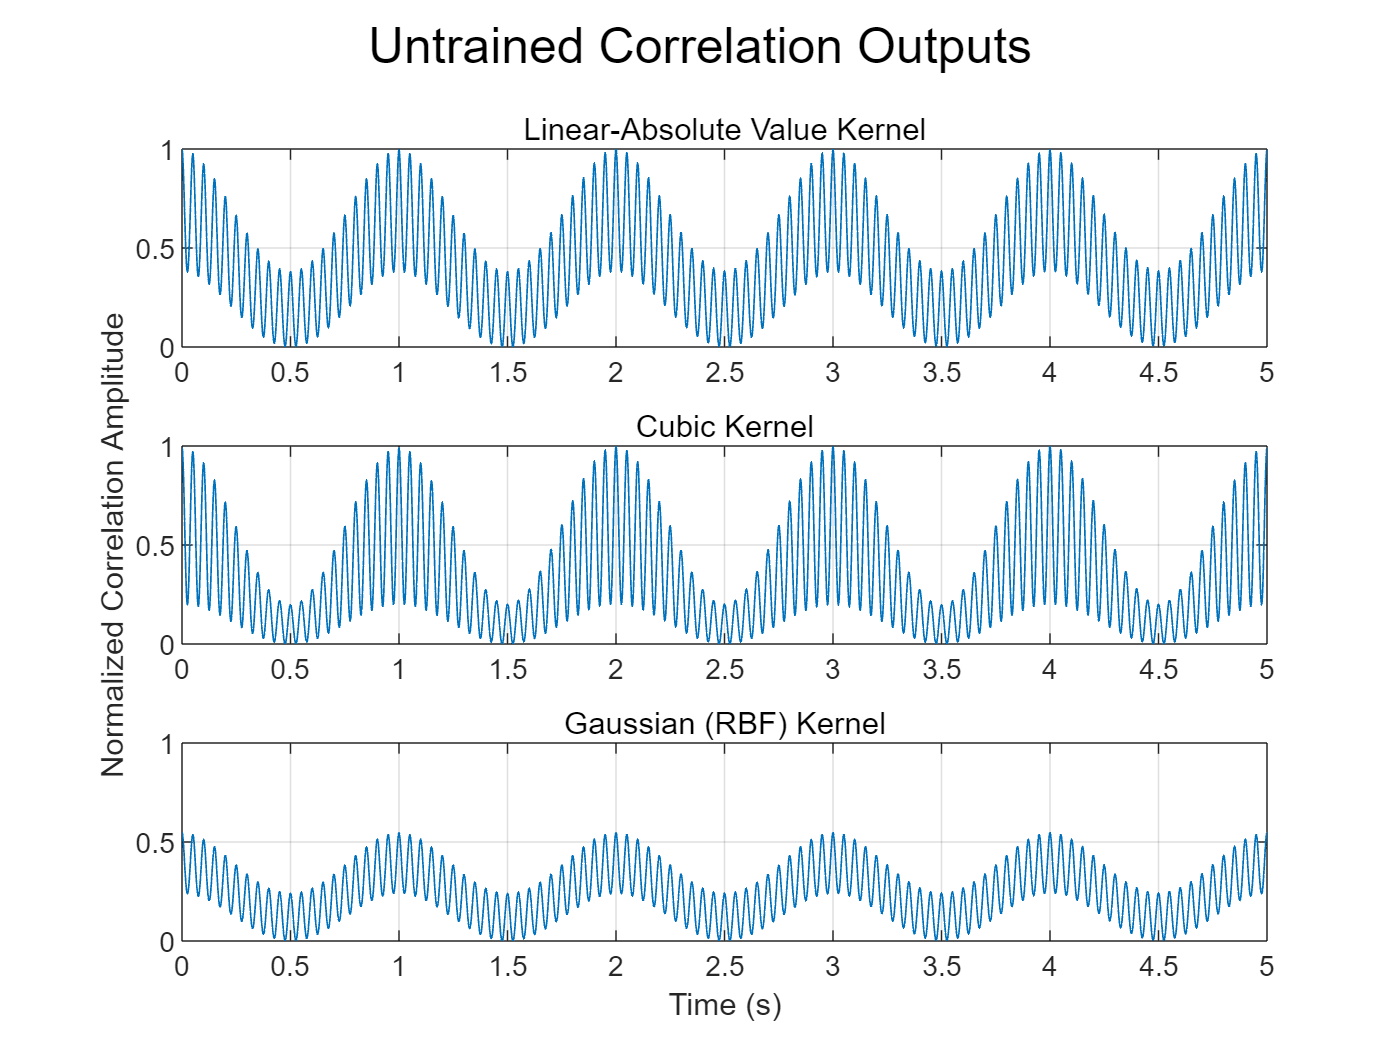

% --Linear abs value correlations
    Kxx = Labs_kernel(signal, signal);
    Kyy = Labs_kernel(ref_signal_long, ref_signal_long);

    Kxxf = fft(Kxx);
    Kyyf = fft(Kyy);

    Rxyf = Kxxf .* conj(1 .* Kyyf);
    Rxy = ifft(Rxyf);
    Rxy_LAbs_1 = Rxy - min(Rxy);
    Rxy_LAbs = Rxy_LAbs_1 ./ max(Rxy_LAbs_1);

% --Cubic correlations
    Kxx = cubic_kernel(signal, signal);
    Kyy = cubic_kernel(ref_signal_long, ref_signal_long);

    Kxxf = fft(Kxx);
    Kyyf = fft(Kyy);

    Rxyf = Kxxf .* conj(1 .* Kyyf);
    Rxy = ifft(Rxyf);
    Rxy = Rxy - min(Rxy);
    Rxy_cubic = Rxy./max(Rxy);

% --Gaussian Kernel
    Kxx = RBF_kernel(signal, signal, 0.1);
    Kyy = RBF_kernel(ref_signal_long, ref_signal_long, 0.1);

    Kxxf = fft(Kxx);
    Kyyf = fft(Kyy);

    Rxyf = Kxxf .* conj(1 .* Kyyf);
    Rxy = ifft(Rxyf);
    Rxy = Rxy - min(Rxy);
    Rxy_RBF = Rxy./max(Rxy_LAbs_1);

% --Plot
    figure()
    subplot(3,1,1)
    plot(t1, Rxy_LAbs)
        hold on 
        grid on
        subtitle('Linear-Absolute Value Kernel')

    subplot(3,1,2)
    plot(t1, Rxy_cubic)
        grid on
        subtitle('Cubic Kernel')
        ylabel('Normalized Correlation Amplitude')

    subplot(3,1,3)
    plot(t1, Rxy_RBF)
        grid on
        subtitle('Gaussian (RBF) Kernel')
        sgtitle("Untrained Correlation Outputs")
        xlabel('Time (s)')
        ylim([0 1])

All three have peaks that appear within the same place bit will also have different amplitudes. These are all normalized amplitudes for each normalized by the maximum value of the correlation for all three, that being the max value of the Cubic Kernel Correlation. We can see that there is a clear difference in the RBF Kernel that is trained because it has an amplitude that is 1/2 the value of the other two kernels. Amplitude does not matter strictly but it does matter in terms of the meaning, but the amplitude differences between the ecah one because a higher amplitude for a higher correlation could mean a better precision for weak signals.

## Function Definitions

### Linear Absolute Value Kernel

                
$$K(x,y) = |(x + y)|$$


function kf = Labs_kernel(x, y)

    % --Test for fourier domain or real domain
        if isa(x, "complex")

            % --Complete kernel transform
                kf = x - conj(y);
                kf = abs(ifft(kf));

        else 
            % --Complete Kernel Transform
                kf = abs(x + y);

        end
end

### Cubic Kernel

                
$$K(x,y) = -(x \odot y + 1)^3$$


function kf = cubic_kernel(x, y)

    % --Test for data type
        if isa(x, "complex")

            % --complete kernel transform
                x = ifft(x);
                y = ifft(y);

        end

    % --Compute Kernel Transform
         kf = (x.*y + 1).^3;

end

### RBF Kernel

                
$$K(x,y) = exp(\frac{-(x^2 + y^2)}{2\sigma})$$


function kf = RBF_kernel(x, y, sigma)

 % --Test for data type
        if isa(x, "complex")

            % --complete kernel transform
                x = ifft(x);
                y = ifft(y);

        end

    % --Compute Kernel Transform
         kf =  exp(-(x.^2 + y.^2) ./ (2*sigma));

end